# Chapter 1: The French-DeGroot model

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## 1.1 The French-DeGroot model of opinion formation

Describes a DT process of opinion formation in a group of $n$ agents, whose opinions are $x_1, \dots, x_n \text{ with } x_i\in\mathbb R$

System dynamics is described by the stochastic matrix $W = (w_{ij}) \in \mathbb R^{n \times n}$ where $w_{ij}>0, j=1, \dots, n$ defines the influence of agent $j$ on the opinion of agent $i$ at each time-step.

Hence the system equation is 

                                             (M1.1)   $x(k+1) = Wx(k) = \sum_{j = 1}^nw_{ij}x_j(k) \forall i, \ k = 0, 1 , \dots$

The self-influence weight $w_{ii} \ge 0
$ indicates the agent's openness to the assimilation of other's opinions:

- $w_{ii} = 0
$ "open-minded" (completely relies on others' opinions)

- $w_{ii} = 1 \text{ and } w_{ij}=0 \forall j \neq i $ "stubborn" (anchored to its initial opinion $x_i (k) \equiv x_i(0) \text{ for } k = 0, 1 ,\dots
$

Agent's opinions can also be vectors $x^i = (x_{1i}, \dots,x_{mi})$, hence we get the opinion matrix $X = (x_{ii})\in \mathbb R ^ {n \times m}$ and we can rewrite the system dynamics as 

                                                    (M1.2)    $X(k+1) = WX(k), \ k = 0,1, \dots$

Every column $x_i(k) = (x_{1i}(k),\dots x_{ni}(k))^T \in \mathbb R ^n \text{ of } X(k)$ evolves in accordance to M1. Hence M2 with a general stochastic matrix W is referred to as the French-DeGroot model.

## 1.2 Convergence and Conensus Criteria

The dynamics of M1.1 is "non-expansive" in the sense that 

                                                    
$$\min_ix_i(0) \le \dots \le \min_ix_i(k) \le \min_ix_i(k+1) \\
\max_ix_i(0) \ge \dots \ge \max_ix_i(k) \ge \max_ix_i(k+1)$$


for any $k = 0, 1, \dots
$

Such system is Lyapunov stable but it such stability is not asymptotic since $W$ always has eigenvalue at $1$.

Such model is **convergent **if for any initial condition $x(0)$ the limits exists $x(\infty) = \lim_{k \rightarrow \infty}x(k) = \lim_{k \rightarrow \infty}W^kx(0)$. A convergent model reaches consensu if $x_1(\infty) = \dots = x_n(\infty)

$ for any initial coniditon.

We call the matrix $W$**regular **if the limit $W^\infty = \lim_{k\rightarrow \infty} W^k$ exists and **fully regular **if, additionally, the rows of $W^\infty$ are identical (**i.e. **$W^\infty = \mathbb 1_np_\infty^T$ for some $p_\infty \in \mathbb R^n$).

**Lemma 1.1 **The model M1.1 is convergent (ie $W$ regular) $\iff$ $\lambda = 1$ is the only eigenvalue of $W$ on the unit cricle $\left\{ \lambda \in \mathbb C :  | \lambda | = 1\right\}$. Such model reaches consensu (ie $W$ fully regular) $\iff$this eigenvalue is simple, i.e the corresponding eigenspace is spanned by the vector $\mathbb 1$.

**Lemma 1.2 **For an irreducibile stochastic matric $W$ the model M1.1 is convergent $\iff$ $W$ isp rimitive, ie $W^k$ is a positive matrix for large k. In this case consensus is also reached.

%qui metto un semplice esempio applicativo con matrici 2x2

**Lemma 1.3 **If the grap $\mathcal G = \mathcal G[W]$ is stroing, then the model M1.1 reaches a consensu $\iff$ $\mathcal G$ is aperiodic. Otherwise, the model is not convergent and opinions oscillate for almost all $x(0)$.

**Theorem 1.1 **The model M1.1 is convergent $\iff$ all closed strong components in $\mathcal G [W]$ are aperiodic. The model M1.1 reaches a consensus $\iff$ $\mathcal G[W]$ is quasi-strongly connected and the only closed strong component is aperiodic

**Corollary 1.1 **Let the agents' self-weights be positive $w_{ii}>0$ for all $i$. Then, the model M1.1 is convergent. It reaches a consensus $\iff$ $\mathcal G[W]$ is quasi-strongly connected (ie has a directed spanning tree).

## 1.3 French-DeGroot: Dual Markov chain and social power

Consider the French model with $n=3$ agents, corresponding to the following graph                                      

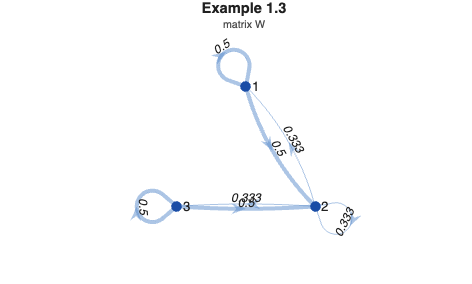

W = [1/2 1/2   0
     1/3 1/3 1/3
       0 1/2 1/2];
plot_graph(W, [], 'Title','Example 1.3', 'Subtitle','matrix W') 

`lot_graph(W, [], 'Title','Example 1.3', 'Subtitle','matrix W') `One can expect that the "central" node 2 corresponds to the most influential sgent in the group. Thisiis confirmed by a straightforward computation: solving the system of equation $p_\infty^T = p_\infty^TW$ and $p_\infty^T \mathbb 1 = 1$, one obtains the vector of social powers $p_\infty^T = (2/7, 3/7, 2/7)$

x0 = [3;-1;5]

x0 =      3
    -1
     5


p  = social_power(W);          % p' = p'W,  p'1 = 1   ->  [2/7 3/7 2/7]
X  = sim_degroot(W, x0, 10);
plot_opinions(X, [], 'Title','Example 1.3', 'Subtitle','x(k+1) = Wx(k)')
p' * x0                        % the consensus value

ans = 1.8571

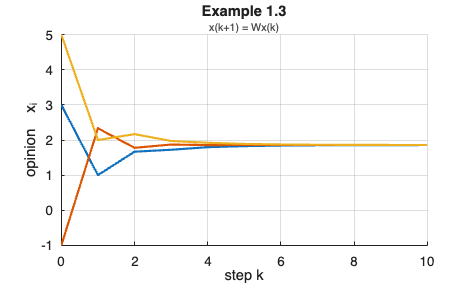

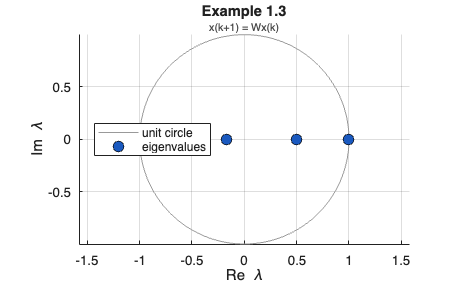

plot_spectrum(W, [],'Title','Example 1.3', 'Subtitle','x(k+1) = Wx(k)')

## 1.4 Stubborn agents in the French-DeGroot model

An agent is said to be **stubborn** if its opinion remains unchanged, independent of the other's opinions.

If the opinions obey the model  M1.1 then the agent $i$ is stubborn $x_i(k)\equiv x_i(0)$ $\iff$ $w_{ii}=1$. Such an agent corresponds to a source node in a graph $\mathcal G[W]$, ie a node having no incoming arcs but for the self-loop. **Theorem 1.1** implies that if $\mathcal G[W]$ has the only source, then the opinions reach a consensus (the source node is the opnly closed strong component of the graph).

If more than one stubborn agent exist (ie $\mathcal G[W]$ has several sources), then consensus among them is, obviously, impossible.  **Theorem 1.1** implies, however, that typically the opinions in such a group converge.

**Corollary 1.2 **Let the group have $s\ge1$ stubborn agents, influencing all other individuals (ie the set of source nodes is connected by walks to all other nodes of $\mathcal G[W]$. Then the model M1.1 is convergent.

Indeed, source nodes are the only closed strong components of $\mathcal G[W]$, which are obiously aperiodic.

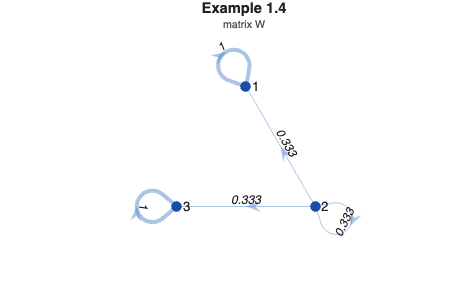

W = [1 0 0
     1/3 1/3 1/3
       0 0 1];
plot_graph(W, [], 'Title','Example 1.4', 'Subtitle','matrix W') 


x0 = [3;-1;5]

x0 =      3
    -1
     5


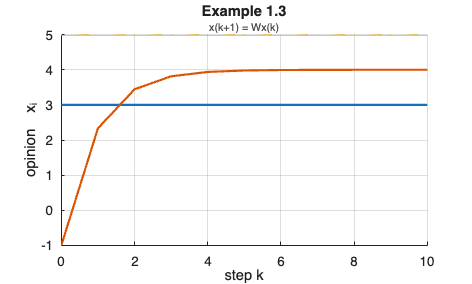

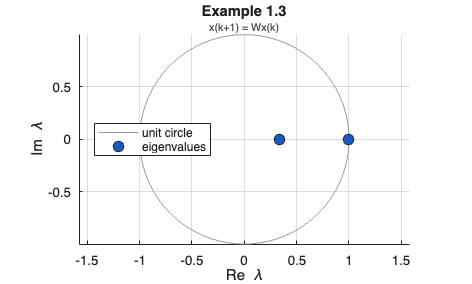

X  = sim_degroot(W, x0, 10);
plot_opinions(X, [], 'Title','Example 1.3', 'Subtitle','x(k+1) = Wx(k)')
plot_spectrum(W, [],'Title','Example 1.3', 'Subtitle','x(k+1) = Wx(k)')

## 1.5 Examples